clc
close all
clear
%% 导入数据
figureUnits = 'centimeters';
figureWidth = 25; 
figureHeight = 15;
%===========================导入数据===========================
load("C:\Users\Administrator\Desktop\optimal\optimal_compress_wes@are\compare_DTW_ARE_MSE_GZ\-9.4±7_re1e6_0.6\data_collection_ARE.mat")
S_ARE = trapz(ARE_data(:,1) ,ARE_data(:,2));
[max_ARE,i_ARE] = max(ARE_data(:,2));
[min_ARE,j_are] = min(ARE_data(:,2));
MAX_ARE = [max_ARE,ARE_data(i_ARE,1)];
MIN_ARE = [min_ARE,ARE_data(j_are,1)];

load("C:\Users\Administrator\Desktop\optimal\optimal_compress_wes@are\compare_DTW_ARE_MSE_GZ\-9.4±7_re1e6_0.6\data_collection_DTW.mat")
S_DTW = trapz(DTW_data(:,1) ,DTW_data(:,2));
[max_DTW,i_DTW] = max(DTW_data(:,2));
[min_DTW,j_dtw] = min(DTW_data(:,2));
MAX_DTW = [max_DTW,DTW_data(i_DTW,1)];
MIN_DTW = [min_DTW,DTW_data(j_dtw,1)];

load("C:\Users\Administrator\Desktop\optimal\optimal_compress_wes@are\compare_DTW_ARE_MSE_GZ\-9.4±7_re1e6_0.6\data_collection_GZ.mat")
S_GZ = trapz(GZ_data(:,1) ,GZ_data(:,2));
[max_GZ,i_GZ] = max(GZ_data(:,2));
[min_GZ,j_gz] = min(GZ_data(:,2));
MAX_GZ = [max_GZ,GZ_data(i_GZ,1)];
MIN_GZ = [min_GZ,GZ_data(j_gz,1)];

S_init= trapz(init_data(:,1) ,init_data(:,2));
[max_init,i_init] = max(init_data(:,2));
[min_init,j_init] = min(init_data(:,2));
MAX_init = [max_init,init_data(i_init,1)];
MIN_init = [min_init,init_data(j_init,1)];


S_exp = trapz(exp_data(:,1) ,exp_data(:,2));

[exp_up,exp_dw] = area_cover(ARE_data,DTW_data,GZ_data,init_data,exp_data);

EXP_data = [exp_up
            exp_dw];

[max_EXP,i_EXP] = max(EXP_data(:,2));
[min_EXP,j_exp] = min(EXP_data(:,2));
MAX_EXP = [max_EXP,EXP_data(i_EXP,1)];
MIN_EXP = [min_EXP,EXP_data(j_exp,1)];
%===================================计算误差===================================
Error_S = new_areacover(ARE_data,DTW_data,GZ_data,init_data,exp_data);

Error_M = process_mat_data(MAX_ARE,MAX_DTW,MAX_GZ,MAX_init,MAX_EXP);

Error_m= process_mat_data(MIN_ARE,MIN_DTW,MIN_GZ,MIN_init,MIN_EXP);

Error_cob = (1-Error_S)*0.7 + Error_M*0.15 + Error_m*0.15;



Error_ARE = dataprocess_ARE(ARE_data,DTW_data,GZ_data,init_data,EXP_data);

Error_DTW = dataprocess_DTW(ARE_data,DTW_data,GZ_data,init_data,exp_data);

Error_GZ = dataprocess_GZ(ARE_data,DTW_data,GZ_data,init_data,EXP_data);


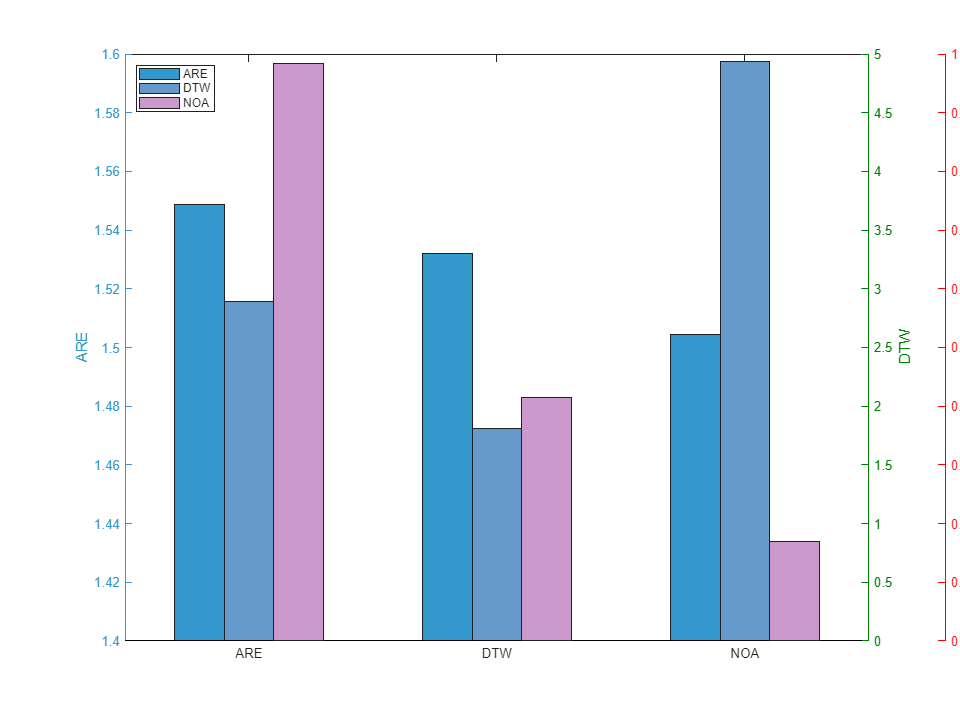

% fig = figure('Color','w','Position',[100 100 100 100]);
%===========================开始绘图===========================
fig = figure(Position=[0 0 960 720]);
x = [0.5 1.5 2.5];
y1 = Error_ARE';
y2 = Error_DTW';
y3 = Error_GZ';
baroffset = 0.2;
offset = 0.08;
color1 = [0.2 0.6 0.8];
color2 = [0.4 0.6 0.8];
color3 = [0.8 0.6 0.8];

%===========================图1===========================
ax(1) = axes('Parent',fig);
bar(x-baroffset, y1, 0.2, 'FaceColor',color1);
ax(1).YColor = color1;
xlim([0 3])
ylim([1.4 1.6])
ax(1).XTick = x;
categories = {'ARE', 'DTW', 'NOA'};
xticklabels(categories)
ax(1).YLabel.String = 'ARE';
%===========================图2===========================
ax(2) = axes('Parent',fig);
bar(x, y2, 0.2, 'FaceColor',color2);
set(ax(2),'YAxisLocation','right','Color','none','YColor',[0 0.5 0],...
    'xlim',get(ax(1),'xlim'),'xtick',[],'box','off','XColor','k');
ax(2).YLabel.String = 'DTW';
% Determine the position of the third axes
pos = ax(1).Position;
pos4 = [pos(1) pos(2) pos(3)+offset pos(4)];

%===========================图3===========================
ax(3) = axes('Parent',fig);
bar(x+baroffset, y3, 0.2, 'FaceColor',color3);
set(ax(3),'box','off',...
   'Color','none','XColor','none','YColor','none',...   
   'xtick',[],'xlim',get(ax(1),'xlim'),'yaxislocation','right',...
   'XColor','none');

ax(4) = axes('Parent',fig);
plot(0,0);
set(ax(4),'Position',pos4,'box','off',...
   'Color','none','XColor','none','YColor','r',...   
   'xtick',[],'xlim',get(ax(1),'xlim'),'ylim',get(ax(3),'ylim'),'yaxislocation','right',...
   'XColor','none');
ax(4).YLabel.String = 'NOA';
hold(ax(1), 'on')
lg1 = bar(ax(1), nan, nan, 0.2, 'FaceColor', color1);
lg2 = bar(ax(1), nan, nan, 0.2, 'FaceColor', color2);
lg3 = bar(ax(1), nan, nan, 0.2, 'FaceColor', color3);

legend(ax(1), [lg1, lg2, lg3], {'ARE', 'DTW', 'NOA'}, 'Location', 'northwest');
exportgraphics(gcf,'test.pdf','ContentType','vector')